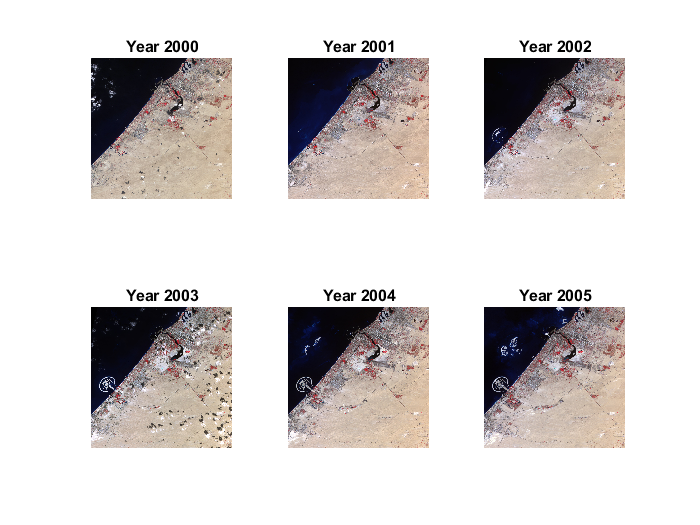


imagefiles = dir('images/*jpg');      
nfiles = length(imagefiles);
currentImages = cell(1,length(imagefiles));
figure;

for ii=1:length(imagefiles)
   currentfilefolder = [ imagefiles(ii).folder , '\', imagefiles(ii).name ];
   currentImage = imread(currentfilefolder);
   currentImages{ii}= currentImage;
   eval(['I' num2str(ii) '=currentImage;']);
end


figure (1);
subplot(2,3,1),imshow(I1),title('Year 2000');
subplot(2,3,2),imshow(I2),title('Year 2001');
subplot(2,3,3),imshow(I3),title('Year 2002');
subplot(2,3,4),imshow(I4),title('Year 2003');
subplot(2,3,5),imshow(I5),title('Year 2004');
subplot(2,3,6),imshow(I6),title('Year 2005');

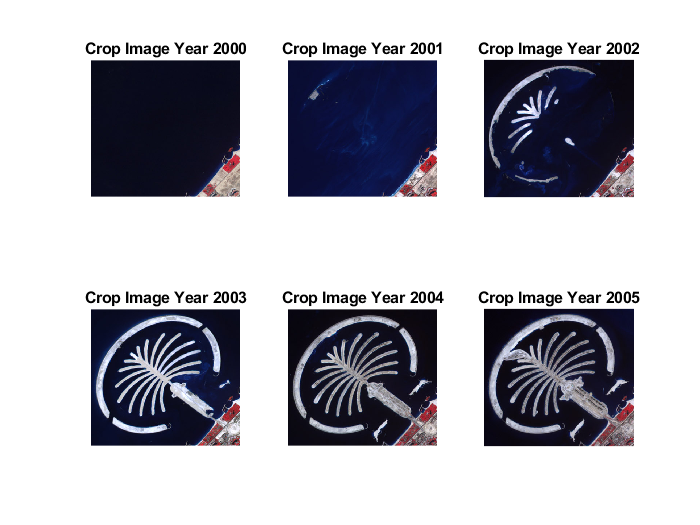



% Crop the Required area into new set of variables.
IC1 = imcrop(I1,[160 1465 410 375]);
IC2 = imcrop(I2,[160 1465 410 375]);
IC3 = imcrop(I3,[160 1465 410 375]);
IC4 = imcrop(I4,[160 1465 410 375]);
IC5 = imcrop(I5,[160 1465 410 375]);
IC6 = imcrop(I6,[160 1465 410 375]);

% To Display and Assigned name to Cropped images.
figure (2);
subplot(2,3,1),imshow(IC1),title('Crop Image Year 2000');
subplot(2,3,2),imshow(IC2),title('Crop Image Year 2001');
subplot(2,3,3),imshow(IC3),title('Crop Image Year 2002');
subplot(2,3,4),imshow(IC4),title('Crop Image Year 2003');
subplot(2,3,5),imshow(IC5),title('Crop Image Year 2004');
subplot(2,3,6),imshow(IC6),title('Crop Image Year 2005');

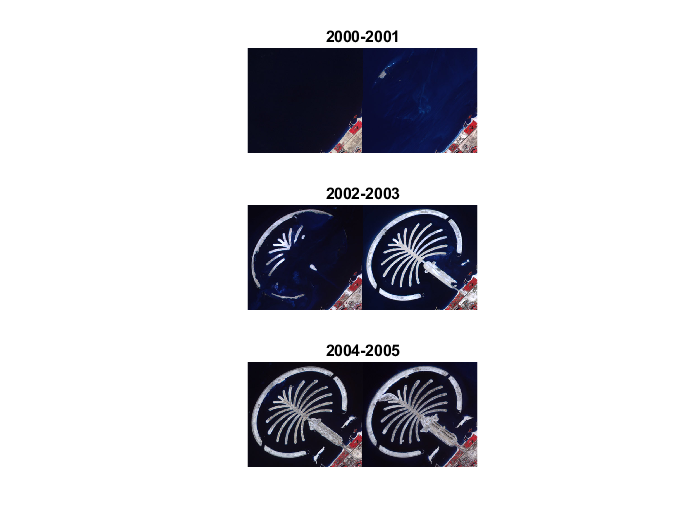


% Comparing starting result and end result of the area
figure(3);
subplot(3,1,1),imshowpair(IC1,IC2,"montage"), title("2000-2001");
subplot(3,1,2),imshowpair(IC3,IC4,"montage"), title("2002-2003");
subplot(3,1,3),imshowpair(IC5,IC6,"montage"), title("2004-2005");

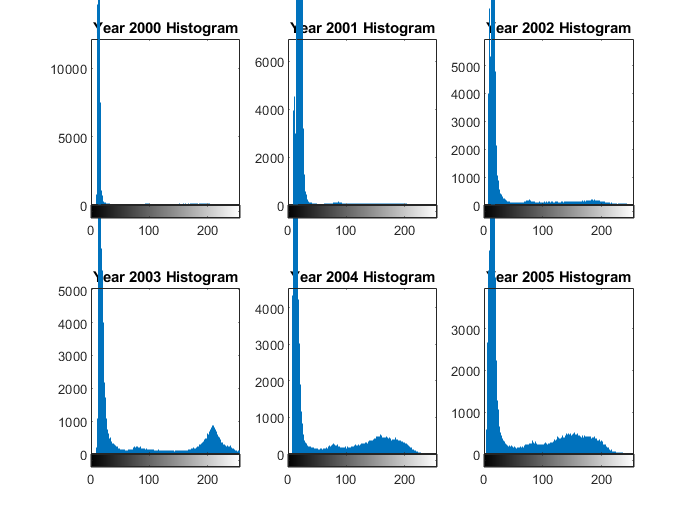



% Convert required area to grayscale image
GrayTC1 = im2gray(IC1);
GrayTC2 = im2gray(IC2);
GrayTC3 = im2gray(IC3);
GrayTC4 = im2gray(IC4);
GrayTC5 = im2gray(IC5);
GrayTC6 = im2gray(IC6);

figure (4);
subplot(2,3,1),imshow(GrayTC1),title('Grayscale Image Year 2000');
subplot(2,3,2),imshow(GrayTC2),title('Grayscale Image Year 2001');
subplot(2,3,3),imshow(GrayTC3),title('Grayscale Image Year 2002');
subplot(2,3,4),imshow(GrayTC4),title('Grayscale Image Year 2003');
subplot(2,3,5),imshow(GrayTC5),title('Grayscale Image Year 2004');
subplot(2,3,6),imshow(GrayTC6),title('Grayscale Image Year 2005');


% Display histogram
figure(4);
subplot(2,3,1),imhist(GrayTC1),title('Year 2000 Histogram');
subplot(2,3,2),imhist(GrayTC2),title('Year 2001 Histogram');
subplot(2,3,3),imhist(GrayTC3),title('Year 2002 Histogram');
subplot(2,3,4),imhist(GrayTC4),title('Year 2003 Histogram');
subplot(2,3,5),imhist(GrayTC5),title('Year 2004 Histogram');
subplot(2,3,6),imhist(GrayTC6),title('Year 2005 Histogram');

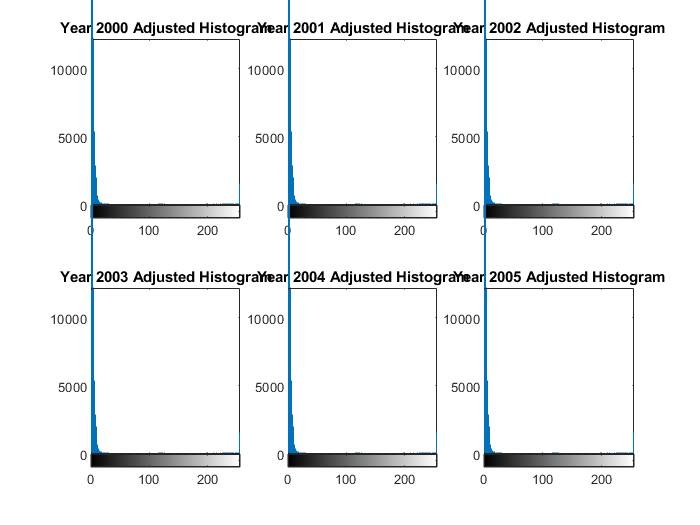



% Adjust Contrast
figure(5);
adjTC1 = imadjust(GrayTC1);
adjTC2 = imadjust(GrayTC2);
adjTC3 = imadjust(GrayTC3);
adjTC4 = imadjust(GrayTC4);
adjTC5 = imadjust(GrayTC5);
adjTC6 = imadjust(GrayTC6);

subplot(2,3,1),imhist(adjTC1),title('Year 2000 Adjusted Histogram');
subplot(2,3,2),imhist(adjTC1),title('Year 2001 Adjusted Histogram');
subplot(2,3,3),imhist(adjTC1),title('Year 2002 Adjusted Histogram');
subplot(2,3,4),imhist(adjTC1),title('Year 2003 Adjusted Histogram');
subplot(2,3,5),imhist(adjTC1),title('Year 2004 Adjusted Histogram');
subplot(2,3,6),imhist(adjTC1),title('Year 2005 Adjusted Histogram');

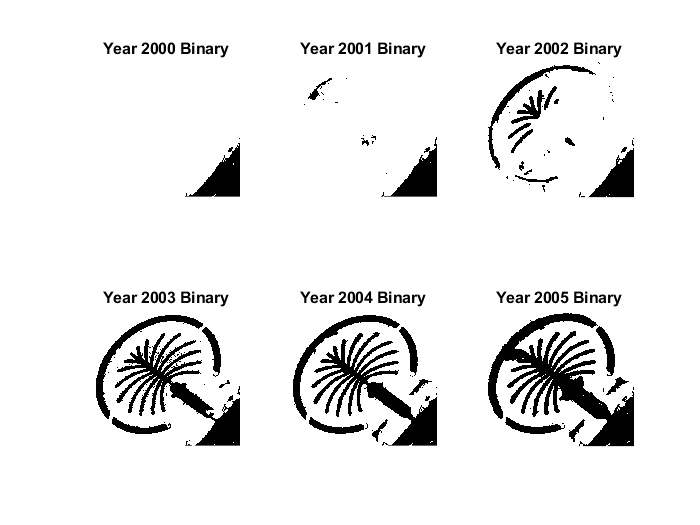




% Converting the original image into a binary image using 
% Function block which is created W.T.H of Colou 
% Threshold app

% Comparing the maskimage (Binary) with the original on with 
% our Function 
bwTC1 = createMask(IC1);
bwTC2 = createMask2(IC2);
bwTC3 = createMask3(IC3);
bwTC4 = createMask4(IC4);
bwTC5 = createMask5(IC5);
bwTC6 = createMask(IC6);


figure(6);
subplot(2,3,1),imshow(bwTC1),title('Year 2000 Binary');
subplot(2,3,2),imshow(bwTC2),title('Year 2001 Binary');
subplot(2,3,3),imshow(bwTC3),title('Year 2002 Binary');
subplot(2,3,4),imshow(bwTC4),title('Year 2003 Binary');
subplot(2,3,5),imshow(bwTC5),title('Year 2004 Binary');
subplot(2,3,6),imshow(bwTC6),title('Year 2005 Binary');

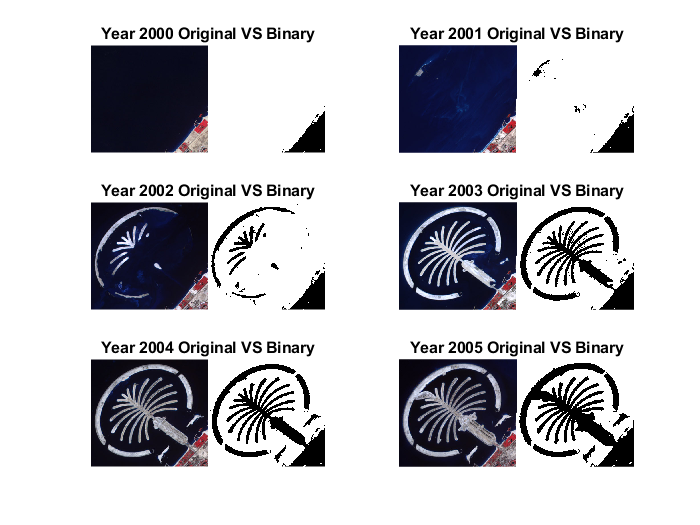


figure(7);
subplot(3,2,1),imshowpair(IC1,bwTC1,"montage"),title('Year 2000 Original VS Binary');
subplot(3,2,2),imshowpair(IC2,bwTC2,"montage"),title('Year 2001 Original VS Binary');
subplot(3,2,3),imshowpair(IC3,bwTC3,"montage"),title('Year 2002 Original VS Binary');
subplot(3,2,4),imshowpair(IC4,bwTC4,"montage"),title('Year 2003 Original VS Binary');
subplot(3,2,5),imshowpair(IC5,bwTC5,"montage"),title('Year 2004 Original VS Binary');
subplot(3,2,6),imshowpair(IC6,bwTC6,"montage"),title('Year 2005 Original VS Binary');

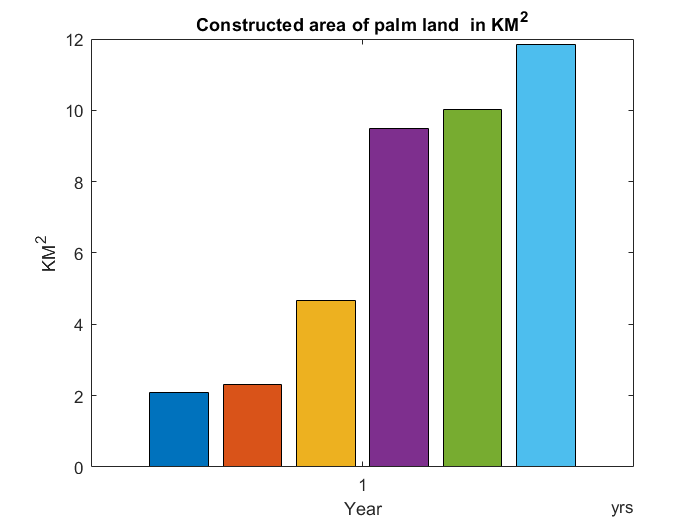



% Calculation the area into Pixels 
% total area 376*411 = 154536
Info_bwTC1 = regionprops("table",bwTC1,"Area");
area_bwTC1_Pixels = 154536 - sum(Info_bwTC1.Area);
Info_bwTC2 = regionprops("table",bwTC2,"Area");
area_bwTC2_Pixels = 154536 - sum(Info_bwTC2.Area);
Info_bwTC3 = regionprops("table",bwTC3,"Area");
area_bwTC3_Pixels = 154536 - sum(Info_bwTC3.Area);
Info_bwTC4 = regionprops("table",bwTC4,"Area");
area_bwTC4_Pixels = 154536 - sum(Info_bwTC4.Area);
Info_bwTC5 = regionprops("table",bwTC5,"Area");
area_bwTC5_Pixels = 154536 - sum(Info_bwTC5.Area);
Info_bwTC6 = regionprops("table",bwTC6,"Area");
area_bwTC6_Pixels = 154536 - sum(Info_bwTC6.Area);

% Calculate the area into Square Kilometers
% as per google map distance from one end to another of land
% is 3 miles which are equal to 4.82803 Km 
% as we have calculated distance using these 2 command
% "imshow(IC6)" "imtool(IC6)" we got our output as 335 Pixels

SqPixel2SqKM = (335/4.82803)^2;

area_bwTC1_SqKM = area_bwTC1_Pixels/SqPixel2SqKM;
area_bwTC2_SqKM = area_bwTC2_Pixels/SqPixel2SqKM;
area_bwTC3_SqKM = area_bwTC3_Pixels/SqPixel2SqKM;
area_bwTC4_SqKM = area_bwTC4_Pixels/SqPixel2SqKM;
area_bwTC5_SqKM = area_bwTC5_Pixels/SqPixel2SqKM;
area_bwTC6_SqKM = area_bwTC6_Pixels/SqPixel2SqKM;

figure(8)
% Plot the area graph 
Years = 2000:1:2005;
areas_SqKM = [area_bwTC1_SqKM,area_bwTC2_SqKM,area_bwTC3_SqKM,area_bwTC4_SqKM,area_bwTC5_SqKM,area_bwTC6_SqKM];
bar(years, areas_SqKM)
title("Constructed area of palm land  in KM^{2}")
xlabel("Year")
ylabel("KM^{2}")

%axis paddedtight
